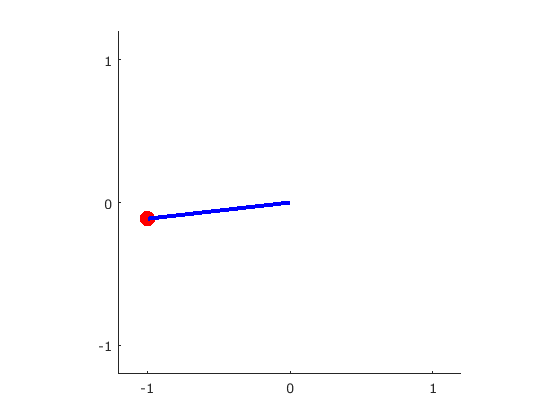

pend([0 10], [pi/2 0], 200)

hfwgwrgwg

% Program 6.3 Animation program for pendulum
% Inputs: time interval inter,
%
% initial values ic=[y(1,1) y(1,2)], number of steps n
% Calls a one-step method such as trapstep.m
% Example usage: pend([0 10],[pi/2 0],200)

function pend(inter,ic,n)
h=(inter(2)-inter(1))/n; % plot n points in total
y(1,:)=ic;
% enter initial conds in y
t(1)=inter(1);
set(gca,'xlim',[-1.2 1.2],'ylim',[-1.2 1.2], ...
'XTick',[-1 0 1],'YTick',[-1 0 1], ...
'Drawmode','fast','Visible','on','NextPlot','add');
cla;
axis square
% make aspect ratio 1 - 1
bob=line('color','r','Marker','.','markersize',40,...
'erase','xor','xdata',[],'ydata',[]);
rod=line('color','b','LineStyle','-','LineWidth',3,...
'erase','xor','xdata',[],'ydata',[]);
for k=1:n
t(k+1)=t(k)+h;
y(k+1,:)=trapstep(t(k),y(k,:),h);
xbob=sin(y(k+1,1)); ybob= -cos(y(k+1,1));
xrod=[0 xbob]; yrod=[0 ybob];
set(rod,'xdata',xrod,'ydata',yrod)
set(bob,'xdata',xbob,'ydata',ybob)
drawnow; pause(h)
end
end

function y=trapstep(t,x,h)
%one step of the Trapezoid Method
z1=ydot(t,x);
g=x+h*z1;
z2=ydot(t+h,g);
y=x+h*(z1+z2)/2;
end

function z=ydot(t,y)
g=9.81;length=1;
z(1)=y(2);
z(2)=-(g/length)*sin(y(1));
end